# Ley de Biot-Savart

El código implementa la ley de Biot-Savart para calcular el campo magnético producido por un arreglo de espiras circulares:

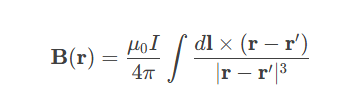

## **Términos y su significado**

- **μ0**� (Permeabilidad del vacío)

- Valor: 4π×10−74*π*×10−7 N/A² (Newtons por Amperio cuadrado).

- Es una constante física que determina cómo se propaga el campo magnético en el vacío.

- En el código:

mu0 = 4*pi*1e-7; % Definición de mu0

 `I`(Corriente eléctrica)

- Es la corriente que circula por las espiras (en Amperes, A).

- En el código:

I = 10; % 10 Amperes

`d``l `(Elemento diferencial de corriente)

- Representa un pequeño segmento del cable por donde fluye la corriente.

- En el código, se calcula como la derivada (usando `gradient`) de las posiciones de las espiras:

dx_total = gradient(x_total); % dl en x
dy_total = gradient(y_total); % dl en y
dz_total = gradient(z_total); % dl en z

**r** (Punto de observación)

- Es la posición donde queremos calcular el campo magnético.

- En el código, se define como una malla de puntos en el plano *x**z*:

[x_grid, z_grid] = meshgrid(xmin:xstep:xmax, zmin:zstep:zmax);

**r**′ (Posición del elemento de corriente dl)

- Es la ubicación del pequeño segmento de corriente en el espacio.

- En el código, se define como las coordenadas de cada punto de la espira:

r_source = [x_total(j); y_total(j); z_total(j)]; % r'

**r**−**r**′ (Vector distancia entre dl y el punto de observación)

- Representa la dirección y distancia desde el elemento de corriente hasta donde medimos **B**.

- En el código:

rx = x_grid - r_source(1); % r - r' en x
ry = -r_source(2);        % r - r' en y (y=0 porque evaluamos en el plano xz)
rz = z_grid - r_source(3); % r - r' en z

`d``l×(r−r′)` (Producto cruz)

- Determina la dirección del campo magnético, que es perpendicular tanto a dl como a **r**−**r**′.

- En el código:

dBx = mu0*I/(4*pi) * (dl(2)*rz - dl(3)*ry) ./ (r_norm.^3); % Componente x
dBz = mu0*I/(4*pi) * (dl(1)*ry - dl(2)*rx) ./ (r_norm.^3); % Componente z

### Discretización de las Espiras

- Parametrización angular: Cada espira se discretiza en `N_theta` segmentos usando coordenadas polares:

theta = linspace(0, 2*pi, N_theta);

2.  Posición de las espiras: Las espiras están espaciadas uniformemente a lo largo del eje z:

z_pos = spacing * (0:N_loops-1);

3. Elementos diferenciales: Se calculan usando `gradient()`, que aproxima numéricamente las derivadas:

dx_total = gradient(x_total);
dy_total = gradient(y_total);
dz_total = gradient(z_total);

### Cálculo del Campo Magnético

El núcleo del cálculo está en el bucle que implementa la ley de Biot-Savart:

- Producto cruz: Se calcula el producto cruz entre el elemento de corriente dl y el vector de distancia r.

dBx = mu0*I/(4*pi) * (dl(2) * rz - dl(3) * ry) ./ (r_norm.^3);
dBz = mu0*I/(4*pi) * (dl(1) * ry - dl(2) * rx) ./ (r_norm.^3);

2. Evitar singularidades: Se excluyen puntos muy cercanos a las fuentes:

valid = r_norm > 1e-6;

### Visualización

- Escala logarítmica: Se usa para mejorar el contraste visual:

Bmag_log = log10(Bmag + 1e-10);

2. Líneas de campo: Se muestran con `streamslice` para visualizar la dirección del campo:

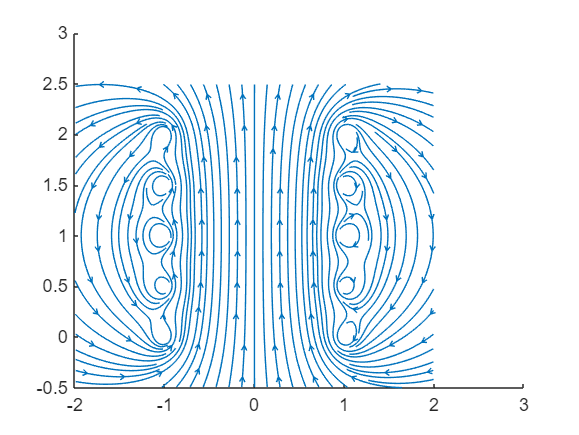

streamslice(xmin:xstep:xmax, zmin:zstep:zmax, Bx, Bz, 2);

Este código simula el campo magnético generado por un arreglo de espiras circulares mediante la implementación numérica de la Ley de Biot-Savart, permitiendo visualizar tanto la intensidad como la dirección del campo en el plano XZ mediante mapas de color logarítmicos y líneas de flujo. La simulación considera parámetros configurables como el número de espiras, su radio, separación y corriente aplicada, ofreciendo una herramienta versátil para estudiar configuraciones electromagnéticas típicas,